# Exercise 4.2 - Pink noise and brownian noise

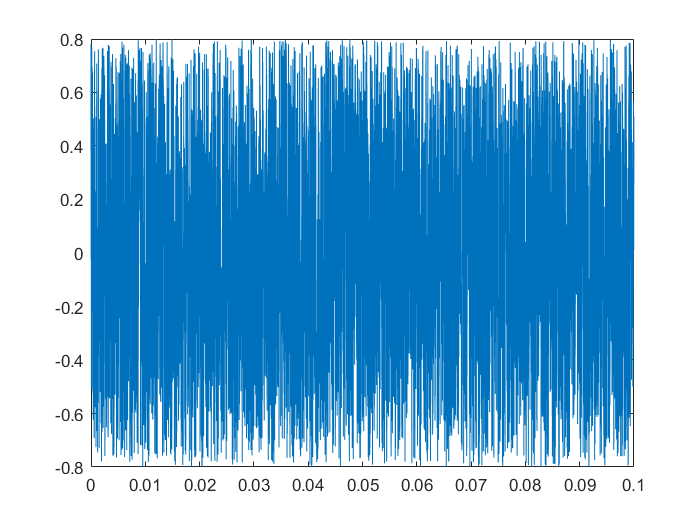

% Import audio files.
[whiteNoise, fs1] = audioread('audio\ruidoblanco.wav');
[pinkNoise, fs2] = audioread('audio\ruidorosa.wav');
[brownNoise, fs3] = audioread('audio\ruidomarron.wav');

% Trim fragments of 100 ms (time domain).
N1 = 0.1 * fs1; % # samples (white noise).
whiteNoiseFrag = whiteNoise(1 : N1);
N2 = 0.1 * fs1; % # samples (pink noise).
pinkNoiseFrag = pinkNoise(1 : N2);
N3 = 0.1 * fs1; % # samples (brownian / red noise).
brownNoiseFrag = brownNoise(1 : N3);

% Play trimmed audio fragments.
%sound(whiteNoiseFrag, fs1);
%sound(pinkNoiseFrag, fs2);
sound(brownNoiseFrag, fs3);

% Allocate vectors with the right sizes to plot the fragments in the time domain.
n1 = 0 : N1 - 1;
n2 = 0 : N2 - 1;
n3 = 0 : N3 - 1;

% Plot all three fragments.
t1 = n1 / fs1;
plot(t1, whiteNoiseFrag);

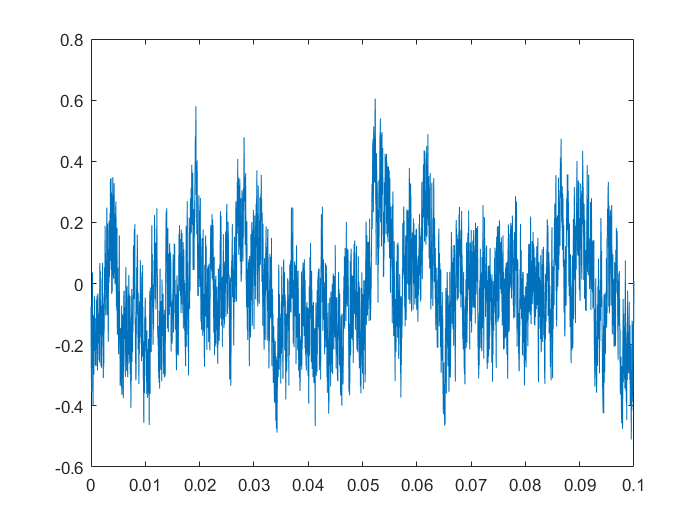

t2 = n2 / fs2;
plot(t2, pinkNoiseFrag);

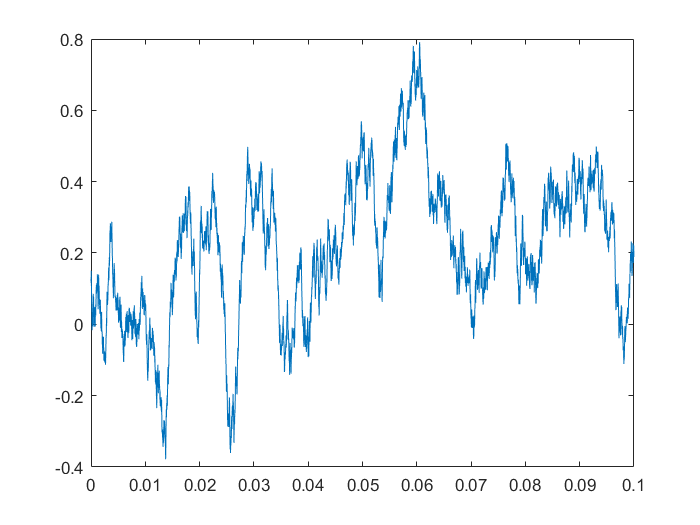

t3 = n3 / fs3;
plot(t3, brownNoiseFrag);

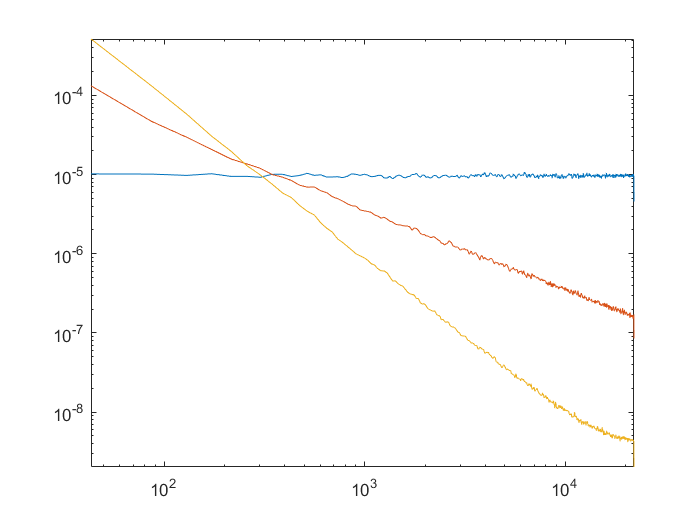


% SPECTRAL ANALYSIS
% Estimate Power Spectral Density (PSD).
[Pxx1, f1] = pwelch(whiteNoise, 1000, 0, [], fs1);
[Pxx2, f2] = pwelch(pinkNoise, 1000, 0, [], fs2); 
[Pxx3, f3] = pwelch(brownNoise, 1000, 0, [], fs3); 

% Plot DSP, to see the distribution of power as a function of frequency. 
% We shall use logarithmic scale.
loglog(f1, Pxx1), hold on
loglog(f2, Pxx2), loglog(f3, Pxx3)
axis([0 fs1/2 -inf inf]);

## Observations

- White noise has a constant power spectral density. That is so because the samples describe a sequence of uncorrelated random variables with uniform probability distribution over the sampling interval.

- Pink noise has higher intensity at lower frequencies. Its power spectral density is inversely proportional to the frequency of the signal, i.e. $\frac{1}{f}$.

- Red / brownian noise has higher intensity at lower frequencies (even more so than pink noise). Its power spectral density is inversely proportional to $f^2$.